% Filtro IIR Butterworth - Pasa bajo - STM32F407
% filipuzzi, fernando rafael
% fecha: 20221024
% matlab2021b

close all; clear all; clc;
digits(300);
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

**Filtro - IIR - Butterworth -  Diseño del filtro Pasa Bajo**

**Parámetros de diseño**

fm=22418;             % Hz,  Frecuencia de Muestreo
fMAX=fm/2;
                           fc=1000;
fp=750 ;                  fs=1250 ;              
Ap=0.3 ;                  As=15 ;     
                        

**Diseño del filtro**

- Transformación de las caracteristicas de frecuencia de paso bajo a paso bajo normalizado.

Fc=fc/fc;
Fs=fs/fc;
Fp=fp/fc;

- Cálculo del Orden del filtro:

N=mi_butter_orden_lp(Fp, Ap, Fs, As)

N =      8


- Función de transferencia y respuesta en frecuencia.

%[Bs,As]=butter(N, 2*pi*fc, 'low','s');
[BS,AS]=mi_butter(N);
sysS=tf(BS,AS)

sysS =
 
                                              1
  -----------------------------------------------------------------------------------------
  s^8 + 5.126 s^7 + 13.14 s^6 + 21.85 s^5 + 25.69 s^4 + 21.85 s^3 + 13.14 s^2 + 5.127 s + 1
 
Continuous-time transfer function.



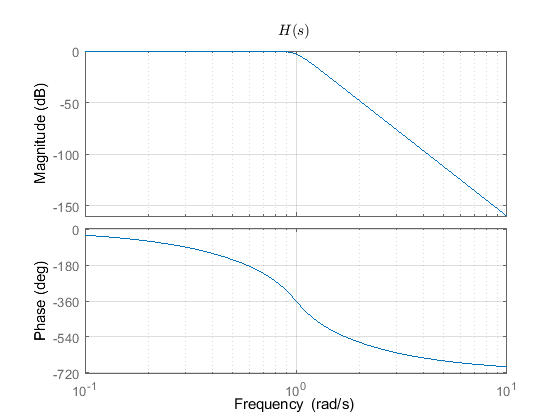

fig0=figure; bode(sysS); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;...
saveas(fig0,'output/stm32_iir_lp_butterworth_0','jpg');

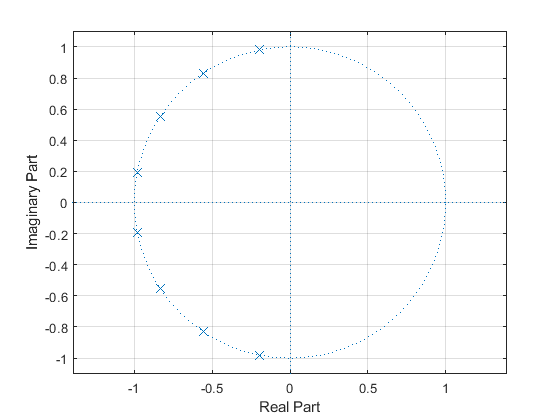

fig1=figure; Np=max(length(BS),length(AS));
zplane( [zeros(1, Np-length(BS)) BS], [  zeros(1, Np-length(AS)) AS] );...
grid on; saveas(fig1,'output/stm32_iir_lp_butterworth_1','jpg');

syms s; ecu_latex = ['H(s)=', latex(poly2sym(BS,s)/poly2sym(AS,s))];
save_ecu('output/stm32_iir_lp_butterworth_ecu_SM.tex', ecu_latex);

- Transformación en frecuencia de paso bajo normalizado a paso bajo

[Bs, As] = mi_lp2lp(BS, AS, 2*pi*fc);
syss=tf(Bs,As)

syss =
 
                                                          
                                                  1.335e42
                                                          
  --------------------------------------------------------------------------------------------------------
                                                                                                          
  5.498e11 s^8 + 1.771e16 s^7 + 2.851e20 s^6 + 2.979e24 s^5 + 2.201e28 s^4 + 1.176e32 s^3 + 4.445e35 s^2  
                                                                                                          
                                                                                    + 1.09e39 s + 1.336e42
                                                                                                          
 
Continuous-time transfer function.



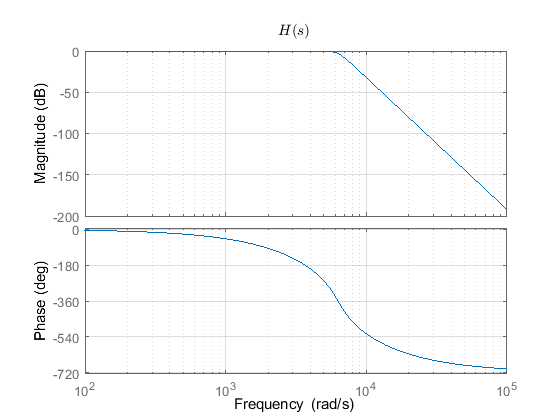

fig2=figure; bode(syss); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;   ...
saveas(fig2,'output/stm32_iir_lp_butterworth_2','jpg');

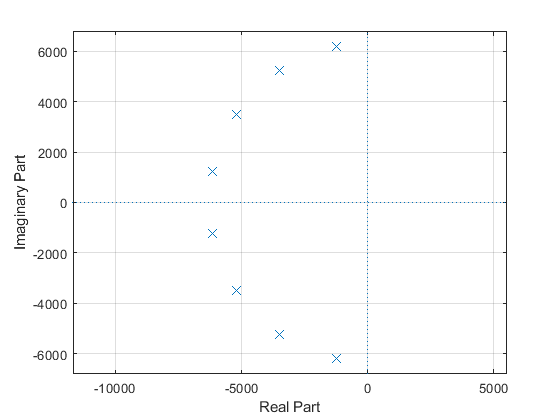

fig3=figure; Np=max(length(Bs),length(As));
zplane( [zeros(1, Np- length(Bs)) Bs  ], [zeros(1, Np- length(As))  As ] ); ...
grid on; saveas(fig3,'output/stm32_iir_lp_butterworth_3','jpg');

syms s; ecu_latex = ['H(s)=', latex(poly2sym(Bs,s)/poly2sym(As,s))];
save_ecu('output/stm32_iir_lp_butterworth_ecu_s.tex', ecu_latex);

**Transformación bilinear - matlab.**

mapeo="bilineal(matlab)";

switch mapeo
    case "integración"
        [Bz, Az]=mi_integral(Bs, As, fm);
    case "invariante al impulso"
        [Bz, Az]=mi_impinvar(Bs, As, fm);
    case "invariante(matlab)"
        [Bz, Az]=impinvar(Bs, As, fm);
    case "bilineal"
        [Bz, Az]=mi_bilinear(Bs, As, fm, fs);
    case "bilineal(matlab)"
        [Bz, Az]=bilinear(Bs, As, fm);   
    case "bilineal-prewarping(matlab)"
        [Bz, Az]=bilinear(Bs, As, fm, fc);   
end
m=max( abs([ Bz, Az ]) ); Bz=Bz/m; Az=Az/m;
Bz=Bz/Az(1); Az=Az/Az(1);
sysz=tf(Bz,Az,1/fm,'Variable','z^-1')

sysz =
 
                                                                                                           
   7.264e-08 + 5.811e-07 z^-1 + 2.034e-06 z^-2 + 4.068e-06 z^-3 + 5.085e-06 z^-4 + 4.068e-06 z^-5          
                                                                                                           
                                                         + 2.034e-06 z^-6 + 5.811e-07 z^-7 + 7.264e-08 z^-8
                                                                                                           
  ----------------------------------------------------------------------------------------------------------
                                                                                                            
  1 - 6.573 z^-1 + 19.01 z^-2 - 31.58 z^-3 + 32.95 z^-4 - 22.11 z^-5 + 9.308 z^-6 - 2.248 z^-7 + 0.2385 z^-8
                                                                                                            
               

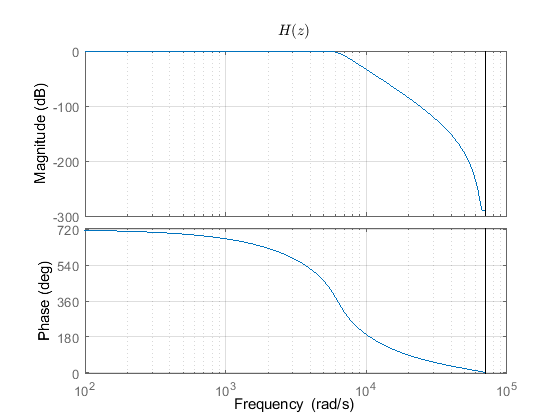

syms z; fig4=figure; bode(sysz); grid on;...
title(sprintf('$$%s$$', 'H(z)'), 'Interpreter','latex');    ...
saveas(fig4, 'output/stm32_iir_lp_butterworth_4', 'jpg');

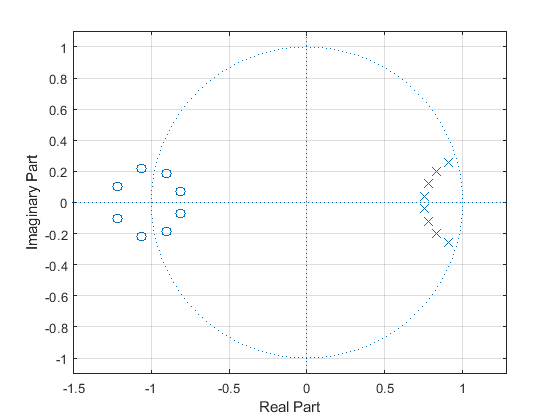

fig5=figure; Np=max( length(Bz),length(Az) );
zplane( [  zeros(1, Np- length(Bz)) Bz], [ zeros(1, Np- length(Az)) Az ] );...
grid on; saveas(fig5,'output/stm32_iir_lp_butterworth_5','jpg');

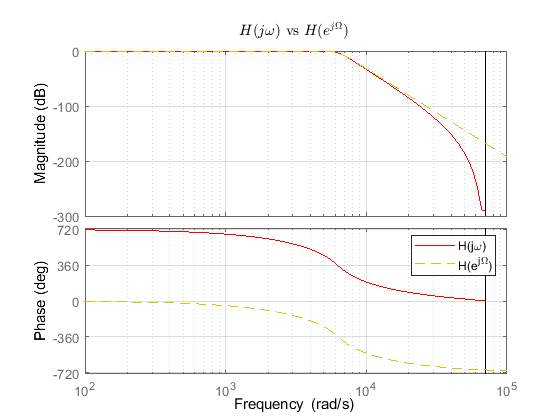

fig6=figure; bode(sysz,'r',syss,'y--'); grid on;...
title(sprintf('$$%s$$', 'H(j\omega)\mbox{ vs }H(e^{j\Omega})'), 'Interpreter','latex');    ...    
legend( sprintf('%s', 'H(j\omega)'), sprintf('%s', 'H(e^{j\Omega})'));   
saveas(fig6,'output/stm32_iir_lp_butterworth_6','jpg');

syms z; ecu_latex = ['H(z)=', latex(poly2sym(Bz,z)/poly2sym(Az,z))];
save_ecu('output/stm32_iir_lp_butterworth_ecu_z.tex', ecu_latex);

**Generación de la linea de código para el micrcontrolador - **vector de coeficientes

PRECISION_STM32=8;
stm32_coef=to_stm32(Bz, Az, N, fm, PRECISION_STM32, 'IIR - Buttherworth - Pasa Bajo', mapeo); ...
saveImplementacion('output/stm32_iir_lp_butterworth_stm32_coef.txt', stm32_coef); ...
fprintf('%s\n',stm32_coef) 

//Filtro IIR - Buttherworth - Pasa Bajo - bilineal(matlab) 
//Orden: 8
//Frecuencia de Muestreo: 22418 (Hz)
#define ORDEN 8
double coef_x[]= {0.00000007,0.00000058,0.00000203,0.00000407,0.00000508, 
			0.00000407,0.00000203,0.00000058,0.00000007};
double coef_y[]= {-1.00000000,6.57310282,-19.01044364,31.58305647,-32.95401793, 
			22.10607950,-9.30763126,2.24834098,-0.23850553};


**Generación de la linea para inicializar el callback de simulink**

simulink_coef=to_simulink(Bz, Az, N, fm, PRECISION_STM32, 'IIR - Butterworth - Pasa Bajo', mapeo); ...
saveImplementacion('output/stm32_iir_lp_butterworth_simulink_coef.txt', simulink_coef); ...
fprintf('%s\n', simulink_coef) 

	%Filtro IIR - Butterworth - Pasa Bajo - bilineal(matlab) 
	%Orden: 8
	%Frecuencia de Muestreo: 22418 (Hz)
	Fm=22418;
	ORDEN=8;
	coef_x= [7.2638518e-08,5.8110813e-07,2.0338785e-06,4.0677569e-06,5.0846963e-06, ...
			4.0677569e-06,2.0338785e-06,5.8110813e-07,7.2638519e-08];
	coef_y= [-1,6.5731028,-19.010444,31.583056,-32.954018, ...
			22.106079,-9.3076313,2.248341,-0.23850553];


save('output/stm32_iir_lp_butterworth.mat');